# Find Corresponding Interest Points Between Pair of Images

Find corresponding interest points between a pair of images using local neighbhorhoods and the Harris algorithm. 

Read the two images - having common scene within them.

I1 = rgb2gray(imread('img1.jpg'));
I2 = rgb2gray(imread('img2.jpg'));

Find the Harris Corners:

points1 = detectHarrisFeatures(I1);
points2 = detectHarrisFeatures(I2);

Extract the neighborhood features

[features1,valid_points1] = extractFeatures(I1,points1);
[features2,valid_points2] = extractFeatures(I2,points2);

Match the features:

indexPairs = matchFeatures(features1,features2);

Retrieve the locations of the corresponding points for each image:

matchedPoints1 = valid_points1(indexPairs(:,1),:);
matchedPoints2 = valid_points2(indexPairs(:,2),:);

Visualize the corresponding points. You can see the effect of translation between the two images despite several erroneous matches:

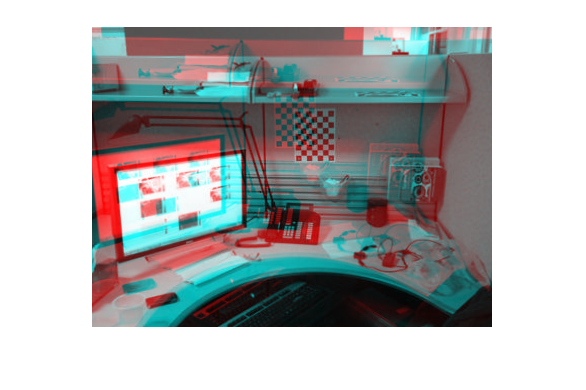

figure; 

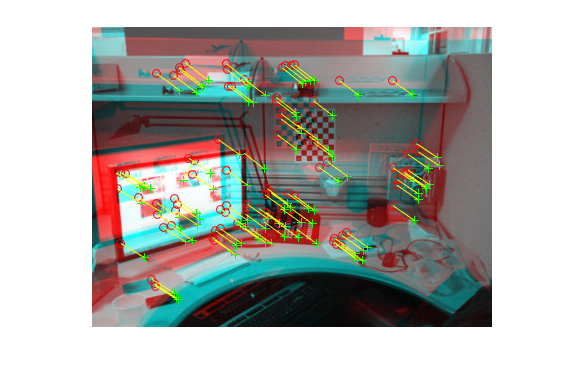

showMatchedFeatures(I1,I2,matchedPoints1,matchedPoints2);